# Organize Hardware Train Data

clear vars; close all; clc;
warning('off','all')

% End seconds (assuming dt = 0.01)
idx_end = 450;
numObs = 3;

## Pick Training Data

[files,path] = uigetfile('*.mat',...
   'Select One or More Files', ...
   'MultiSelect', 'on');

## Conslidate Training Data

oData = consolidateSSMTrainData(path, files, center=false, addInput=true);

Load HW train Data f:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf it/s]



% For autonomous system
% oData = consolidateSSMTrainData(path, files, center=false, addInput=false, idx_end=idx_end);

## Plot Raw Data

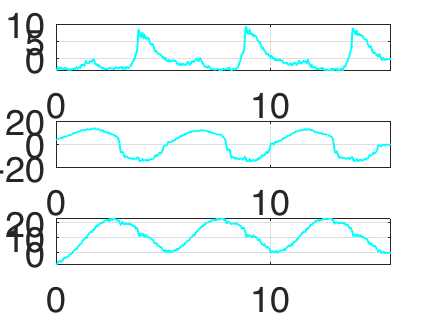

customFigure('subPlot',[numObs 1]);
% labels = ["$x_a$", "$y_a$", "$z_a$", ...
%     "$x_b$", "$y_b$", "$z_b$", ...
%     "$x_c$", "$y_c$", "$z_c$", ...
%     "$x_d$", "$y_d$", "$z_d$", ...
%     "$x_e$", "$y_e$", "$z_e$"];
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numObs
    subplot(numObs,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end

obsIdx = [13 14 15];
for iTraj = 1:size(oData, 1)
    for iObs = 1:numObs
        subplot(numObs,1,iObs);
        oData{iTraj, 1} = oData{iTraj,1}(1:end);
        oData{iTraj, 2} = oData{iTraj,2}(:, 1:end);
        plot(oData{iTraj,1}(1:end),oData{iTraj,2}(obsIdx(iObs),1:end),'Linewidth',1)
    end
end